clc; clear;

R = 4570

R = 4570

Xc = 5643.8

Xc = 5.6438e+03

Z = 7262

Z = 7262

theta = -acos(R/Z)

theta = -0.8901


theta_lin = linspace(0, theta)

theta_lin =          0   -0.0090   -0.0180   -0.0270   -0.0360   -0.0450   -0.0539   -0.0629   -0.0719   -0.0809   -0.0899   -0.0989   -0.1079   -0.1169   -0.1259   -0.1349   -0.1439   -0.1529   -0.1618   -0.1708   -0.1798   -0.1888   -0.1978   -0.2068   -0.2158   -0.2248   -0.2338   -0.2428   -0.2518   -0.2607   -0.2697   -0.2787   -0.2877   -0.2967   -0.3057   -0.3147   -0.3237   -0.3327   -0.3417   -0.3507   -0.3597   -0.3686   -0.3776   -0.3866   -0.3956   -0.4046   -0.4136   -0.4226   -0.4316   -0.4406


center=[0;0]

center =      0
     0


radius=2000

radius = 2000

xcoords = center(1)+radius*cos(theta_lin)

xcoords = 1.0e+03 *

    2.0000    1.9999    1.9997    1.9993    1.9987    1.9980    1.9971    1.9960    1.9948    1.9935    1.9919    1.9902    1.9884    1.9864    1.9842    1.9818    1.9793    1.9767    1.9739    1.9709    1.9677    1.9645    1.9610    1.9574    1.9536    1.9497    1.9456    1.9414    1.9370    1.9324    1.9277    1.9228    1.9178    1.9126    1.9073    1.9018    1.8961    1.8903    1.8844    1.8783    1.8720    1.8656    1.8591    1.8524    1.8455    1.8385    1.8314    1.8241    1.8166    1.8090


ycoords = center(2)+radius*sin(theta_lin)

ycoords = 1.0e+03 *

         0   -0.0180   -0.0360   -0.0539   -0.0719   -0.0899   -0.1078   -0.1258   -0.1437   -0.1617   -0.1796   -0.1975   -0.2154   -0.2332   -0.2511   -0.2689   -0.2867   -0.3045   -0.3223   -0.3400   -0.3577   -0.3754   -0.3930   -0.4107   -0.4282   -0.4458   -0.4633   -0.4808   -0.4982   -0.5156   -0.5330   -0.5503   -0.5675   -0.5848   -0.6019   -0.6191   -0.6361   -0.6532   -0.6701   -0.6870   -0.7039   -0.7207   -0.7374   -0.7541   -0.7708   -0.7873   -0.8038   -0.8203   -0.8366   -0.8529


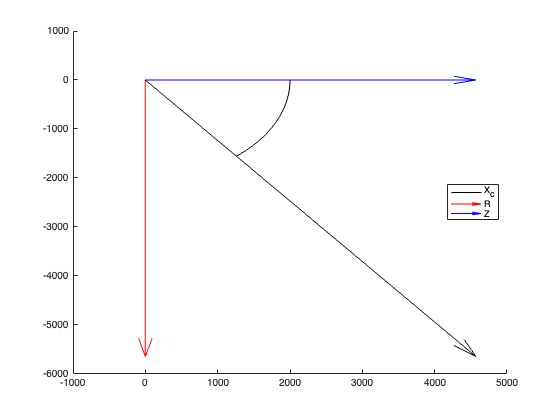



figure
hold on
plot(xcoords,ycoords,'k')
quiver(0, 0, 0, -Xc, 0, "filled", 'r')
quiver(0, 0, R, 0, 0, "filled", 'b')
quiver(0, 0, cos(theta)*Z, sin(theta)*Z, 0, "filled", 'k')

legend(["X_c", "R", "Z"], Location="east")
hold off


E = [
        3.96/3.93;
        3.943/3.956;
        3.90/4.0;
        3.60/4.01;
        3.10/3.995;
        2.64/3.994;
        2.29/4.07;
        1.96/3.944;
]

E =     1.0076
    0.9967
    0.9750
    0.8978
    0.7760
    0.6610
    0.5627
    0.4970



f = [
    251.4;
    500.4;
    991;
    1954;
    3008;
    4030;
    5040;
    6033
]

f = 1.0e+03 *

    0.2514
    0.5004
    0.9910
    1.9540
    3.0080
    4.0300
    5.0400
    6.0330



f_co = 2567

f_co = 2567

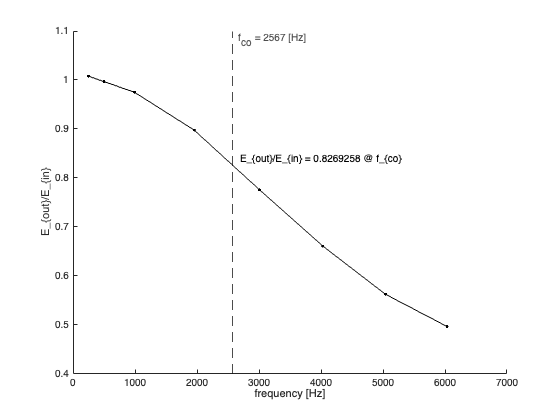


figure
hold on
plot(f, E, "-k", Marker=".")
xline(f_co, "Color", "Black", "LineWidth", 1, "LineStyle","--", Label="f_{co} = 2567 [Hz]", LabelOrientation="horizontal")
xlabel("frequency [Hz]")
ylabel("E_{out}/E_{in}")
text(f_co+125, 0.8269258+0.0125, "E_{out}/E_{in} = 0.8269258 @ f_{co}")